## Polar Overturning Conceptual Model

#### Live script to run experiments and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20, Sep '20, Oct '23

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory. Crop them to make publication-ready figures.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
more off
% clc
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84)
    parpool('local',16) 
end

Exp 1b: Northern hemisphere Fram Strait/Barents Sea Opening with updated parameters from Tsubouchi et al. (2023) in October '23.

model1b = build_POC_model('NH_FSBSO_can_Oct23') ;

 Solutions for experiment: [Exp.~1b Fram Strait+BSO] with file suffices: [NH_FSBSO_can_Oct23]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.7261          |           35.0087          |            3.9000
 Atlantic Water to shelf:             3.7261          |           35.0087          |   0.0212   0.0301   1.9777
 Polar    Water:                     -1.8638          |           34.2596          |  -3.8992  -3.8980  -0.0194
 Overflow Water:            -0.3526   1.6443   1.8498 |  34.6939  34.7778  34.8889 |  -3.8642  -0.0662  -0.0650
 Shelf    Water:            -1.8853  -1.9082  -2.2015 |  34.6284  35.0223  40.0000 |  -1.9471  -0.0041  -0.0006
 

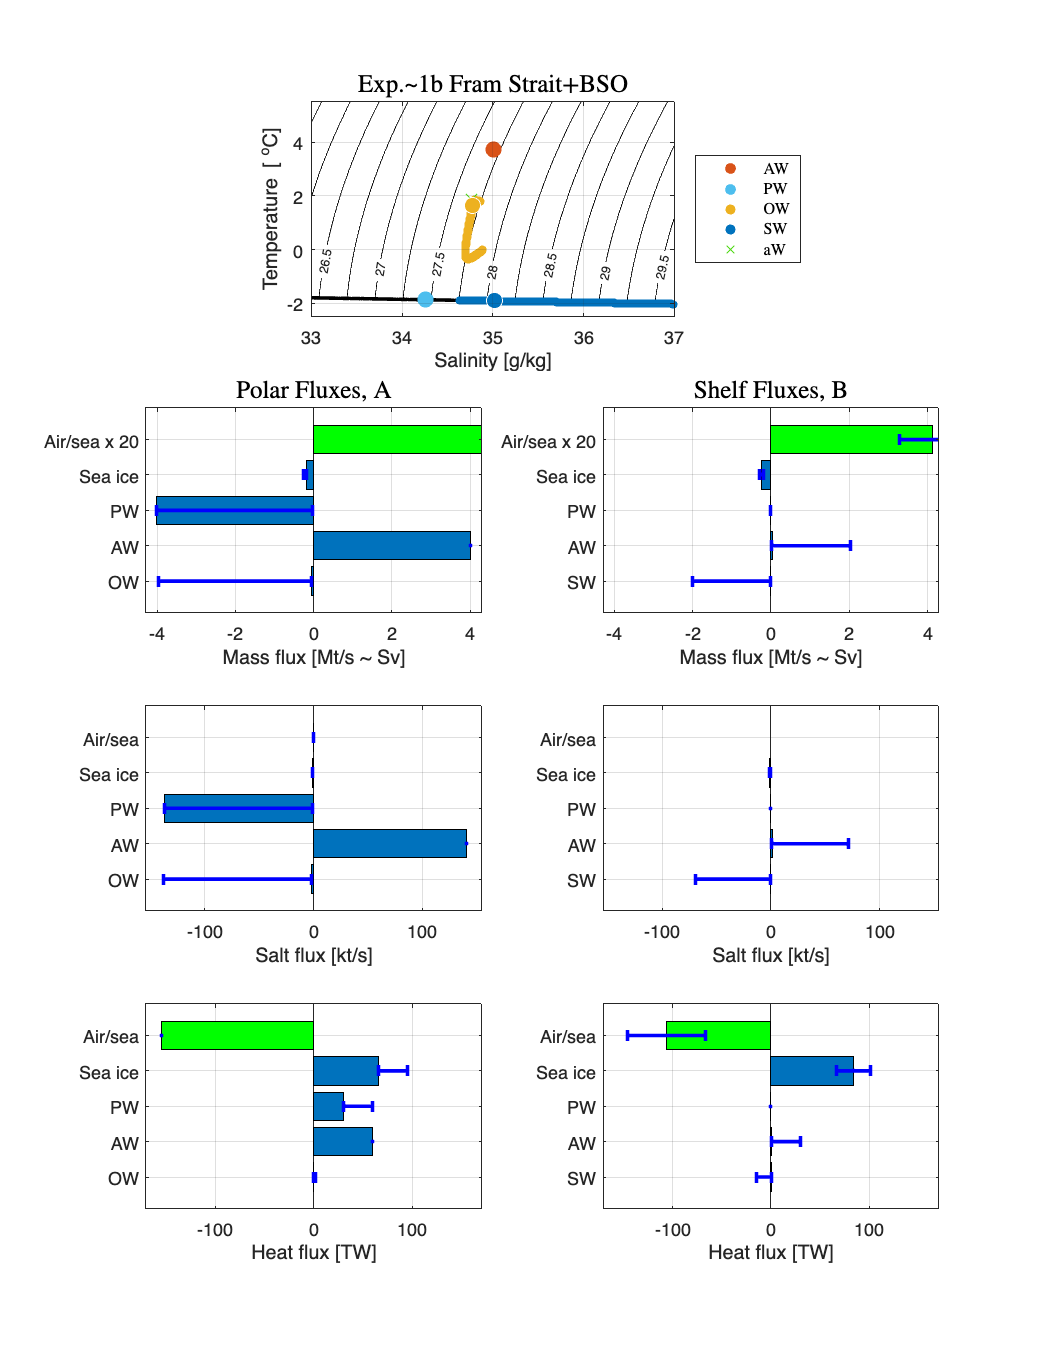

plot_POC_solution(model1b)

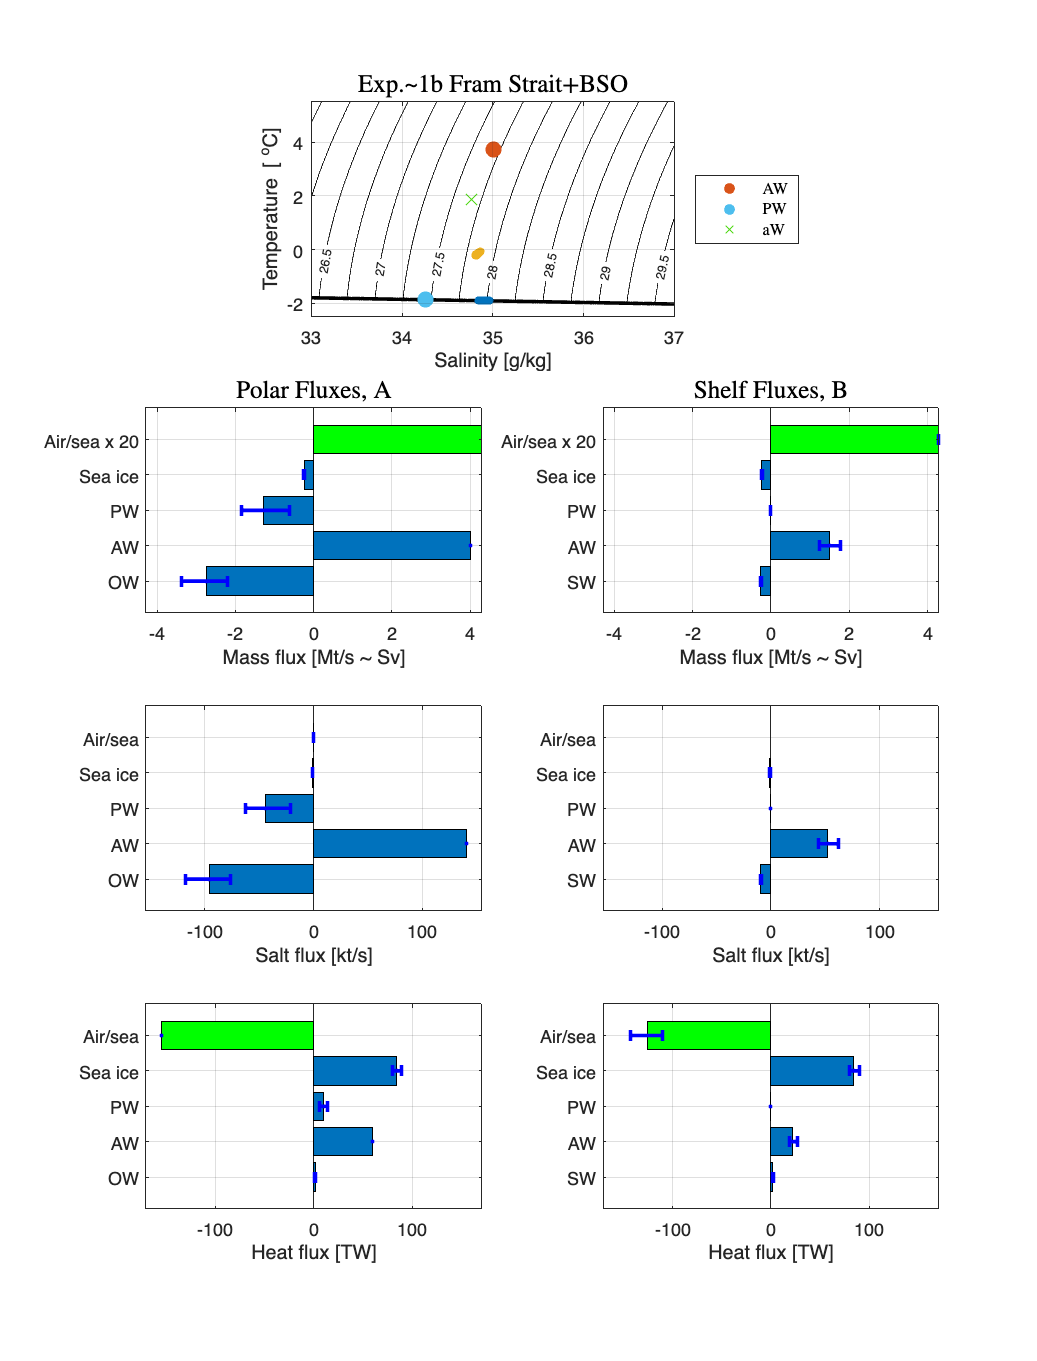

plot_POC_solutionb(model1b)

Exp 3b: Northern hemisphere Fram Strait/Barents Sea Opening with many U_1 values.

model3b = build_POC_model('NH_FSBSO_range_U1') ;

 Solutions for experiment: [Exp.~3b Fram Strait+BSO various $U_1$] with file suffices: [NH_FSBSO_range_U1]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   1.3000   4.5500   7.8000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0206   0.6882   2.7534
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.9208  -1.8324  -0.0000
 Overflow Water:            -1.8908   0.7992   1.8498 |  34.5596  34.8632  35.1123 |  -6.6511  -2.9182  -0.0002
 Shelf    Water:            -1.8809  -1.9956  -2.2015 |  34.5539  36.5174  40.0000 |  -2.74

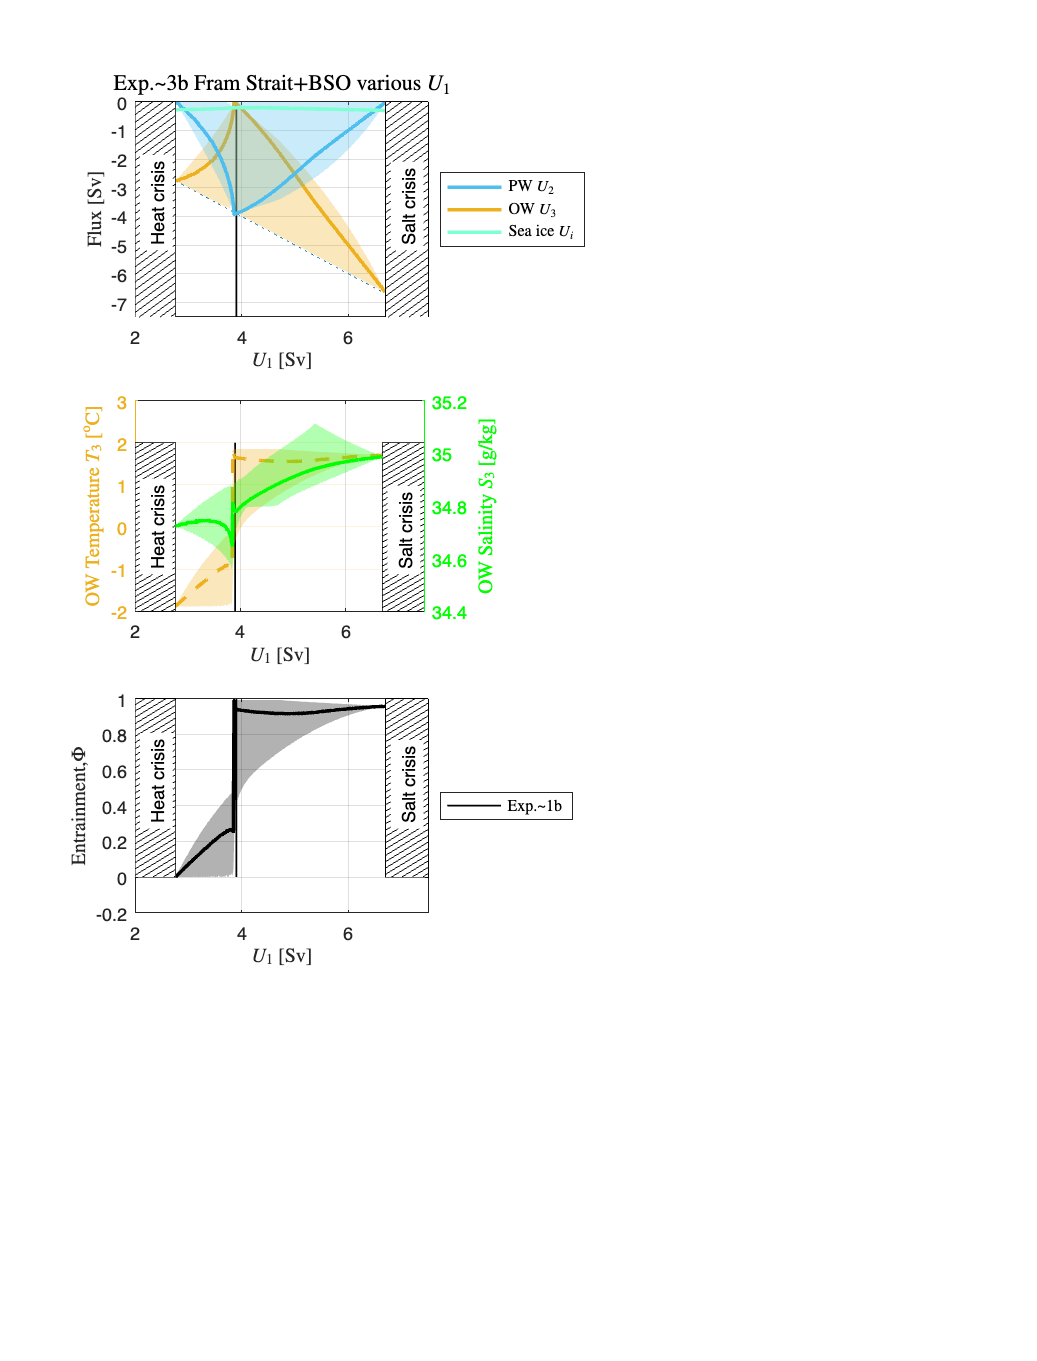

plot_POC_solutions1b(model3b,model1b)

Exp 3c: Northern hemisphere Fram Strait/Barents Sea Opening with many F values.

model3c = build_POC_model('NH_FSBSO_range_F') ;

 Solutions for experiment: [Exp.~3c Fram Strait+BSO various ${\mathcal F}$] with file suffices: [NH_FSBSO_range_F]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   3.9000   3.9000   3.9000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0202   1.2304   3.8814
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.9655  -1.5524  -0.0000
 Overflow Water:            -1.8930   0.2411   1.8498 |  34.5665  34.8204  35.0691 |  -3.9054  -2.3675  -0.0000
 Shelf    Water:            -1.8809  -1.9579  -2.2015 |  34.5539  35.8728  40.0000 

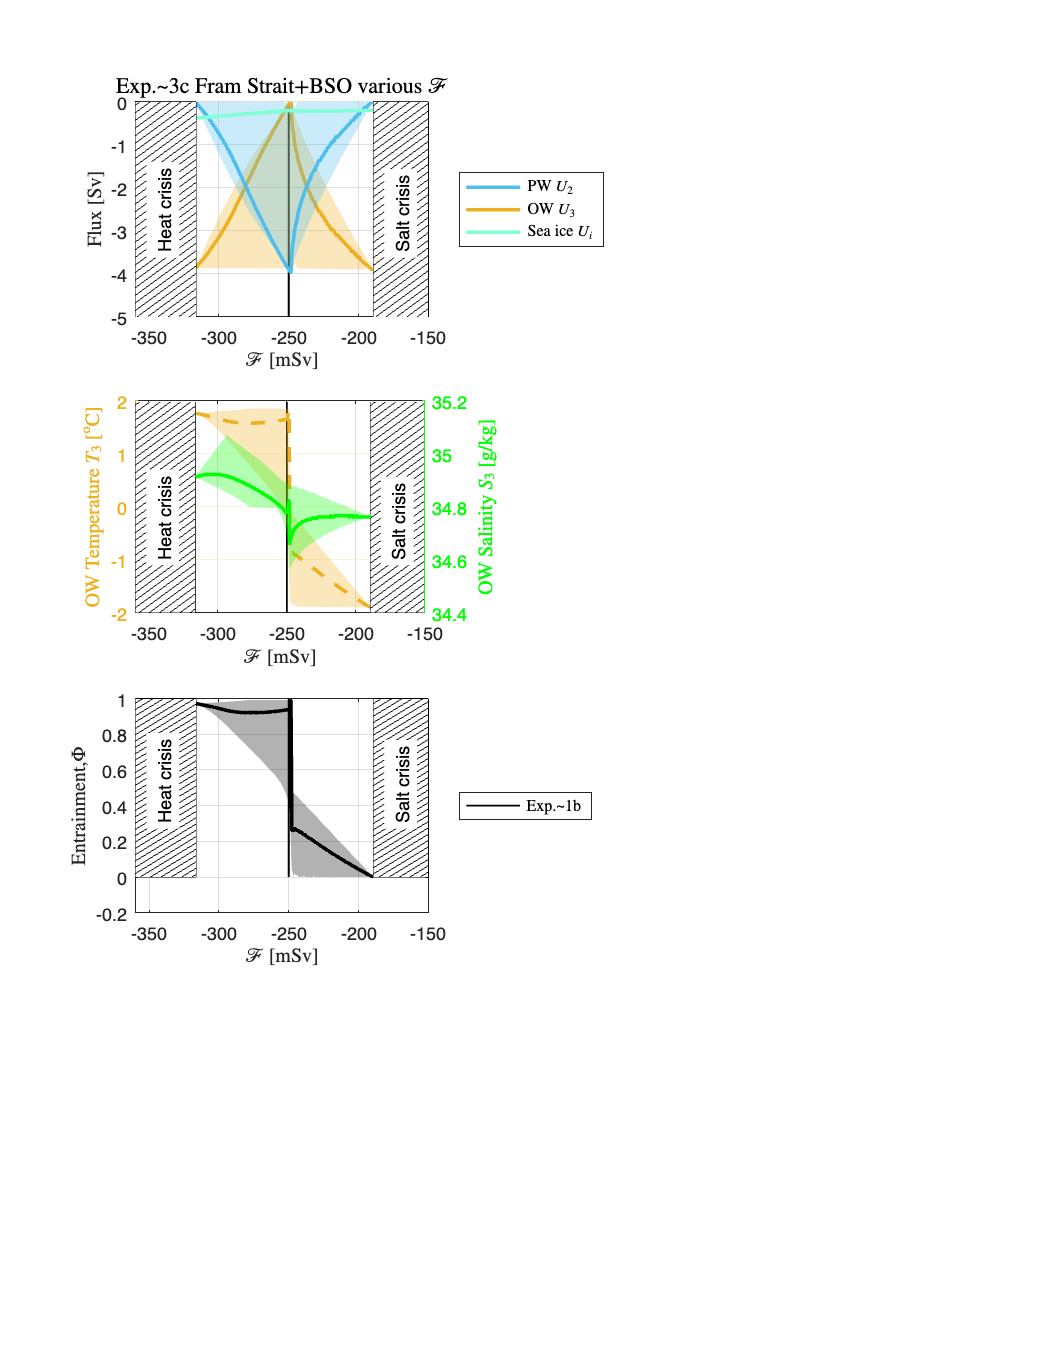

plot_POC_solutions1c(model3c,model1b)

Exp 3d: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

model3d = build_POC_model('NH_FSBSO_range_Q') ;

 Solutions for experiment: [Exp.~3d Fram Strait+BSO various ${\mathcal Q}$] with file suffices: [NH_FSBSO_range_Q]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   3.9000   3.9000   3.9000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0207   1.2186   3.8918
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.9518  -1.5536  -0.0000
 Overflow Water:            -1.8930   0.2436   1.8498 |  34.5664  34.8203  35.0687 |  -3.8984  -2.3666  -0.0132
 Shelf    Water:            -1.8809  -1.9573  -2.2015 |  34.5539  35.8629  40.0000 

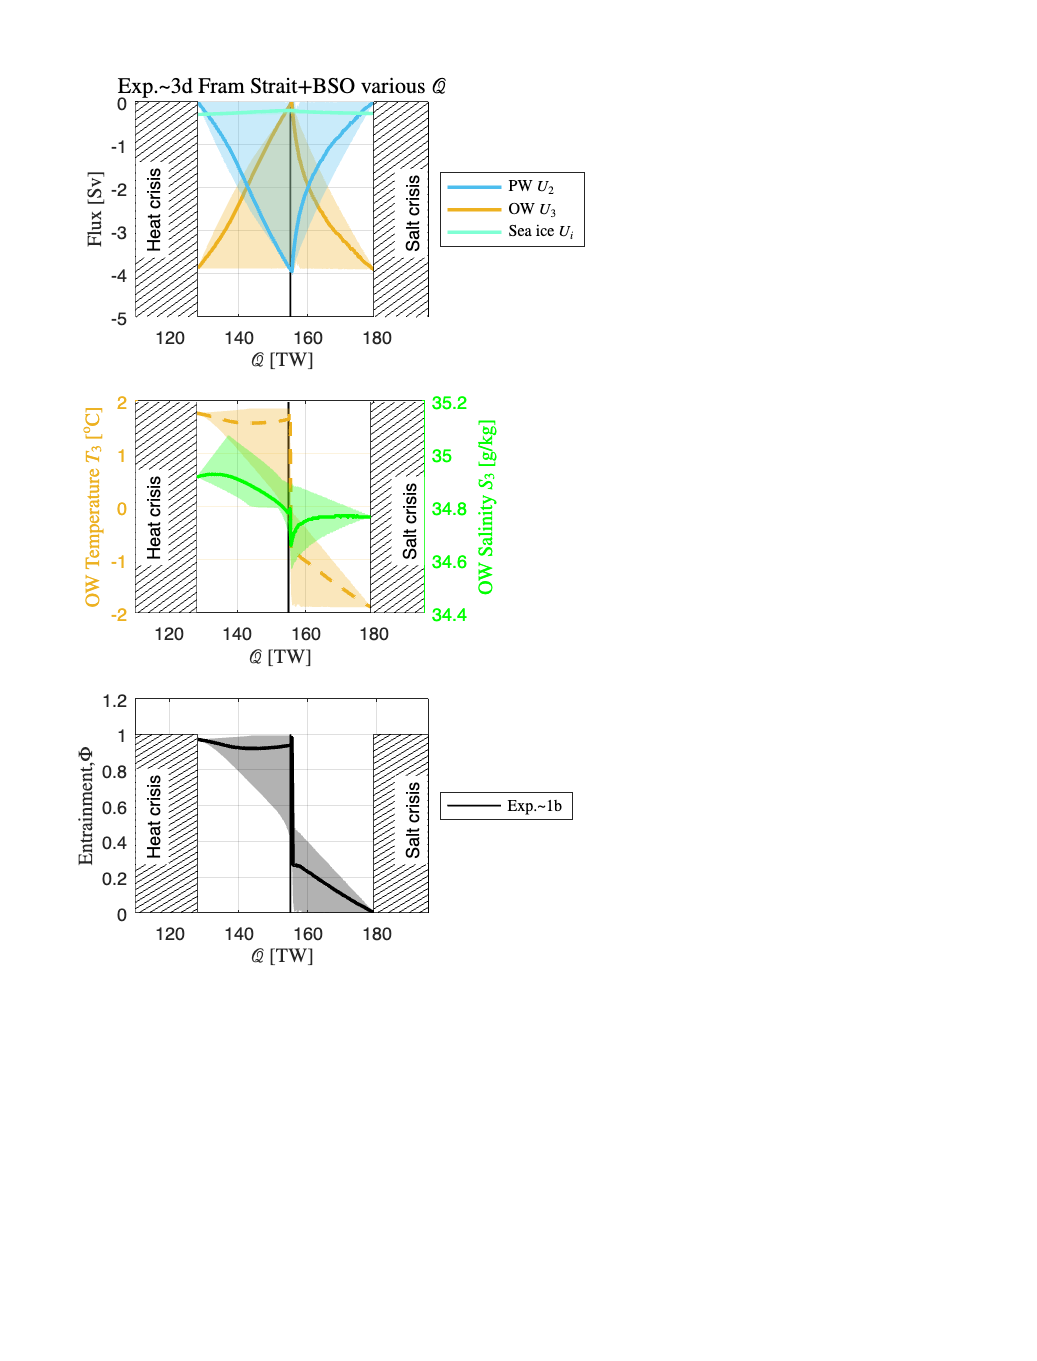

plot_POC_solutions1d(model3d,model1b)

Exp 3e: Northern hemisphere Fram Strait/Barents Sea Opening with many Q, F, U_1 values, based on Tsubouchi et al. (2023).

model3e = build_POC_model('NH_FSBSO_can_Oct23_range') ;

 Solutions for experiment: [Exp.~3d Fram Strait+BSO range] with file suffices: [NH_FSBSO_can_Oct23_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   3.9000   3.9000   3.9000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0159   2.1110   3.8923
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.9334  -1.2878  -0.0000
 Overflow Water:            -1.8930  -0.7202   1.8498 |  34.5592  34.7811  35.0653 |  -3.9091  -2.6313  -0.0250
 Shelf    Water:            -1.8809  -1.9138  -2.2015 |  34.5539  35.1190  40.0000 |  -3.900

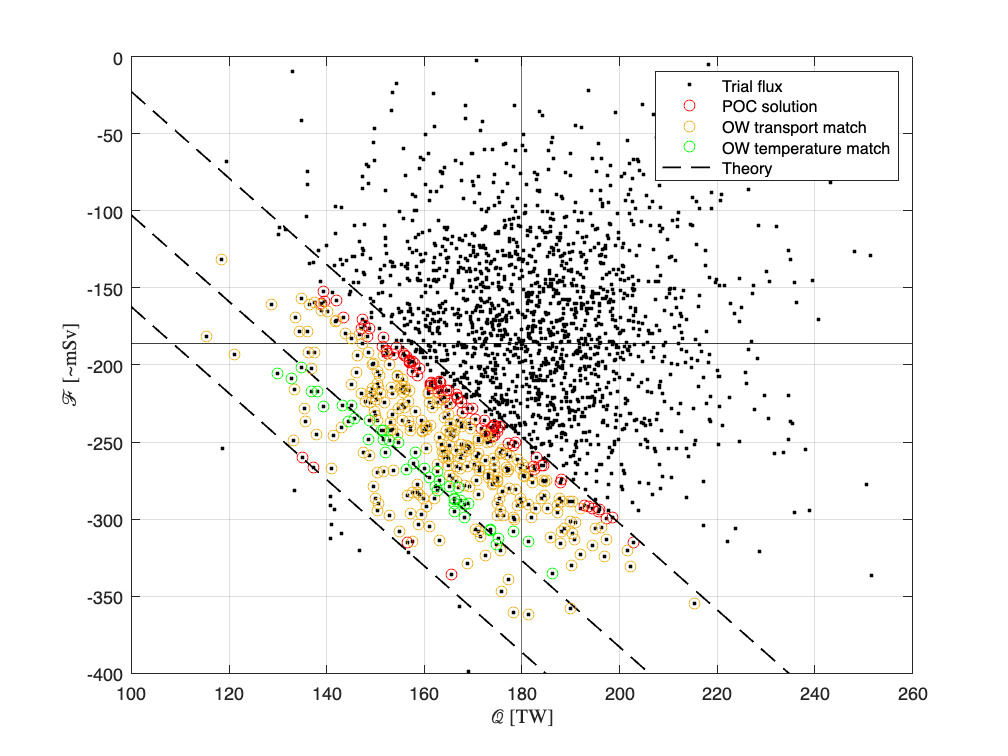

plot_POC_solutions1e(model3e)

Exp 4: Northern hemisphere Fram Strait/Barents Sea Opening with wide range of all parameters.

return
model4 = build_POC_model('NH_FSBSO_sens') ;
plot_POC_solutions2(model4,model3b,model1,model1b)

Exp G1: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM).

return
modelG1 = build_POC_model('NH_FSBSO_LGM_can') ;
plot_POC_solution(modelG1)
modelG1 = build_stable_isotope_model(modelG1) ;

Exp G1b: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with warm AW.

modelG1b = build_POC_model('NH_FSBSO_LGM_hiT1') ;
plot_POC_solution(modelG1b)
modelG1b = build_stable_isotope_model(modelG1b) ;

Exp G2: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with lower Q

modelG2 = build_POC_model('NH_FSBSO_LGM_lowQ') ;
plot_POC_solution(modelG2)
modelG2 = build_stable_isotope_model(modelG2) ;